**Your are given an image which contains a tilted blue rectangle ona a white background.**

**Determine the number of degrees that it is tilted.**

Strategy:

- Rotate the image -1deg at a time

- The image will be level at the angle where the distance between the top-most blue pixel and the bottom-most blue pixel is at its minimum.

Angle=0	 Height=22


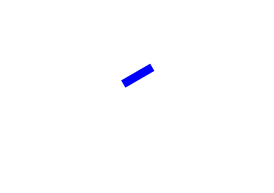

Angle=-15	 Height=16


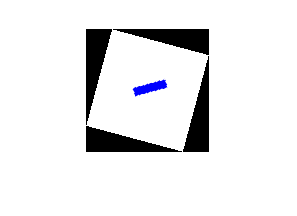

Angle=-30	 Height=7


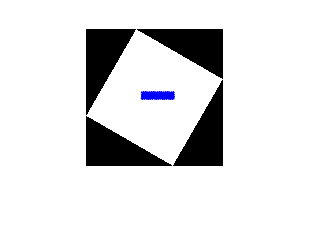

Angle=-45	 Height=15


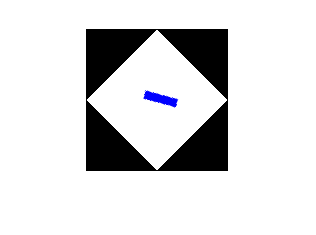

Angle=-60	 Height=22


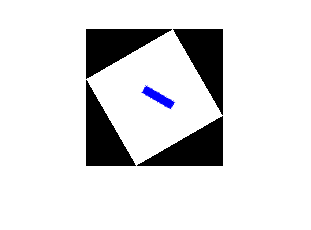

Angle=-75	 Height=28


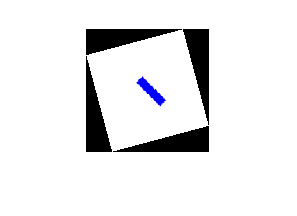

Angle=-90	 Height=31


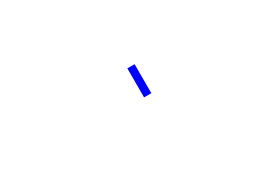

%Read image
img = imread('rotate2.png');

%Since we are looking for the minimum hight on each iteration, set height to infinity to start.
%That way, we a gaurnteed the actual minimum height is less than our initial value.
minHeight = inf;

%By looking at the image, we know that the blue rectangle will be level
%somwhere between 0 and -90 degrees of rotation.
%Set the loop to try each value one degree at a time.
%To illustrate, I will do it in -15deg intervals 
%This loop can easily be changed to do this in -1deg intervals
for a = 0:-15:-90
    %rotate the image
    thisImg = imrotate(img,a); 
    
    %create a mask to detect all blue pixels (0,0,255)
    mask = thisImg(:,:,1)==0 & thisImg(:,:,2)==0 & thisImg(:,:,3)==255;
    
    %find the indecies of the rows inwhich the mask is true
    [rows, cols] = find(mask);
    
    %calculate the number of blue pixels from the top-most to the bootom-most
    thisHeight = max(rows)-min(rows)+1;
    
    %The next 3 lines of code are just for illustration. They are not needed to solve the
    %problem.
    fprintf('Angle=%d\t Height=%d\n',a, thisHeight); %print data to the screen
    
    %start a new figure for each iteration. Without this, we may not get a new image each time. 
    % MATLAB would overwrite our old figures and we would not be able to see the change.
    figure
    imshow(thisImg); %show the image
   
    
    %Check to see if this height is less than our previious minimum, if it
    %is then make it our new minimum.
    if thisHeight < minHeight
        minHeight = thisHeight;
        angle = a;
    end
    
end